%% --- Load and align data ---
data = load('uk_super_clean.mat').uk_super_clean(:, {'Year','Total'});
population = load('uk_pop.mat').uk_pop_final(:, {'Year','Population'});
commonYears = intersect(data.Year, population.Year);
data = data(ismember(data.Year, commonYears), :);
population = population(ismember(population.Year, commonYears), :);
merged = join(data, population, 'Keys', 'Year');

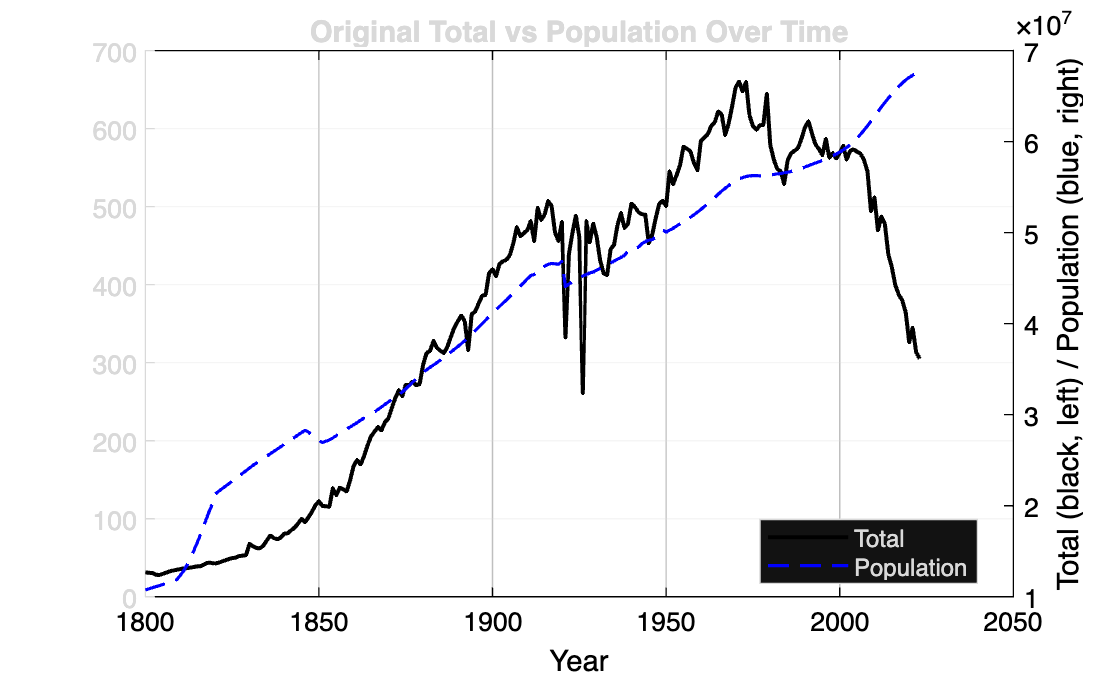

%% --- Visualize original data ---
figure('Color','w');
plot(data.Year, data.Total, 'k-', 'LineWidth', 1.5); hold on;
yyaxis right
plot(population.Year, population.Population, 'b--', 'LineWidth', 1.2);
xlabel('Year');
ylabel('Total (black, left) / Population (blue, right)');
title('Original Total vs Population Over Time');
legend('Total','Population','Location','best');
grid on; box on;
set(gca,'Color','w','XColor','k','YColor','k');

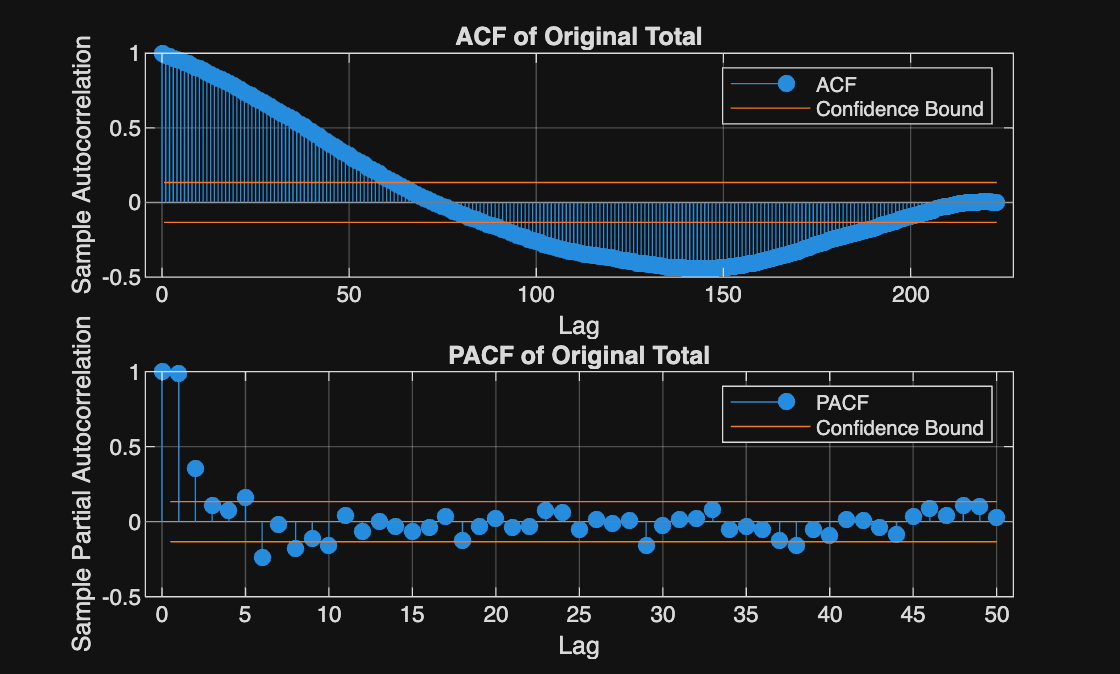

%% --- ACF and PACF of Original Total Data ---
figure;

subplot(2,1,1);
autocorr(merged.Total, 'NumLags', 223);
title('ACF of Original Total');

subplot(2,1,2);
parcorr(merged.Total, 'NumLags', 50);
title('PACF of Original Total');

%% --- Detrend Total with cubic polynomial (centered years) ---
yrs = merged.Year;
yrs_c = yrs - mean(yrs);                    % center years
p = polyfit(yrs_c, merged.Total, 3);        % cubic fit
trend = polyval(p, yrs_c);
merged.Total_detrended = merged.Total - trend;

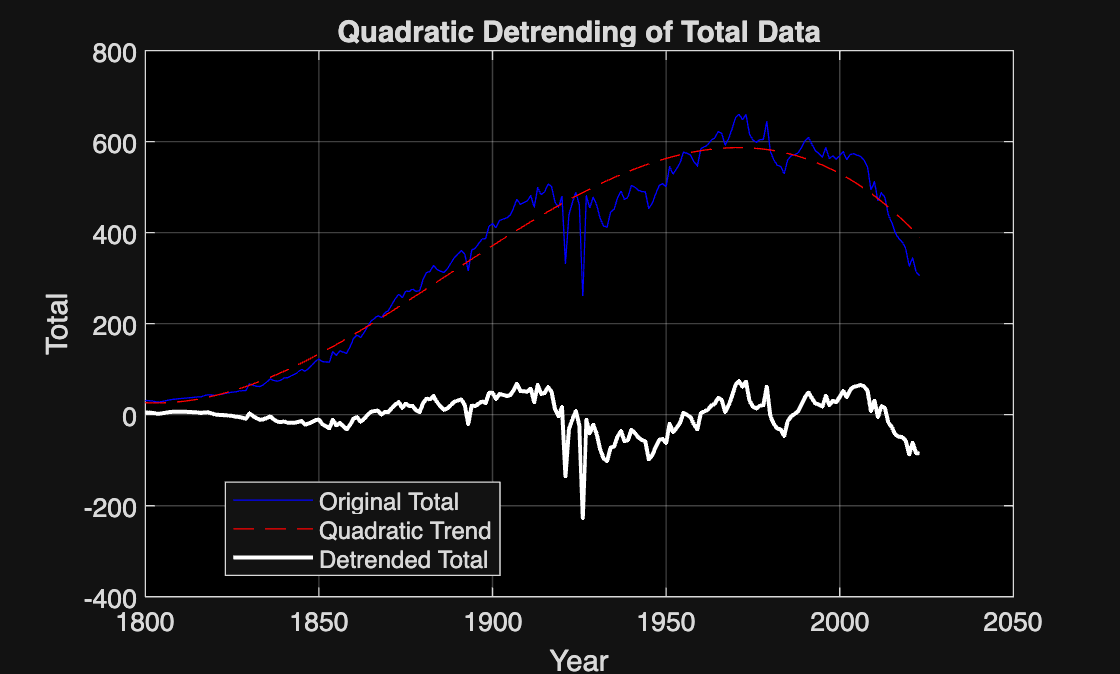

figure;
plot(yrs, merged.Total, 'b', 'DisplayName', 'Original Total');
hold on;
plot(yrs, trend, 'r--', 'DisplayName', 'Quadratic Trend');
plot(yrs, merged.Total_detrended, 'w', 'LineWidth', 1.5, 'DisplayName', 'Detrended Total');
xlabel('Year');
ylabel('Total');
title('Quadratic Detrending of Total Data');
legend('Location', 'best');
grid on;
set(gca, 'Color', 'k'); % optional: black background for visibility
hold off;

%% --- Difference detrended Total to stationarize ---
merged.Total_diff = [NaN; diff(merged.Total_detrended)];
merged = merged(2:end,:); % drop first NaN 

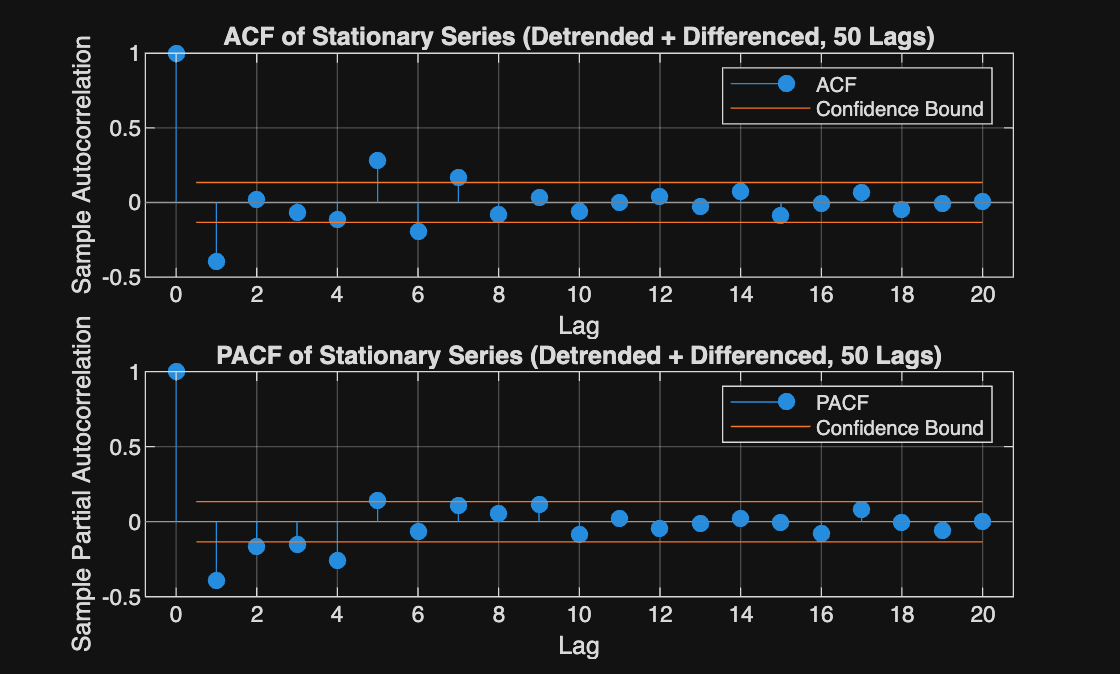

%% --- ACF and PACF of Stationary Series (More Lags) ---
figure;

subplot(2,1,1);
autocorr(merged.Total_diff, 'NumLags', 20);
title('ACF of Stationary Series (Detrended + Differenced, 50 Lags)');

subplot(2,1,2);
parcorr(merged.Total_diff, 'NumLags', 20);
title('PACF of Stationary Series (Detrended + Differenced, 50 Lags)');

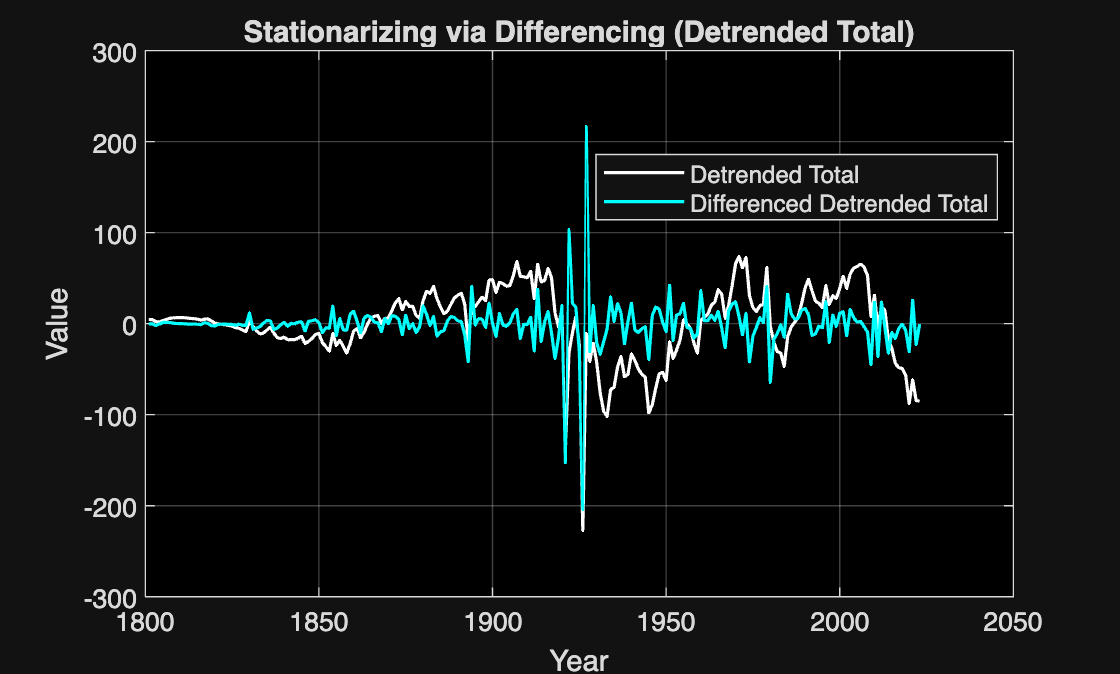

yrs = yrs(2:end);  % keep years consistent with merged after dropping first row

figure;
plot(yrs, merged.Total_detrended, 'w', 'LineWidth', 1.2, 'DisplayName', 'Detrended Total');
hold on;
plot(yrs, merged.Total_diff, 'c', 'LineWidth', 1.2, 'DisplayName', 'Differenced Detrended Total');
xlabel('Year');
ylabel('Value');
title('Stationarizing via Differencing (Detrended Total)');
legend('Location', 'best');
grid on;
set(gca, 'Color', 'k');
hold off;

%% --- Create timetable for ARIMAX ---
TT = table2timetable(merged, 'RowTimes', datetime(merged.Year,1,1));

%% --- Define splits ---
train = TT(TT.Year <= 2013, :);
valid = TT(TT.Year > 2013 & TT.Year <= 2018, :);
train_valid = TT(TT.Year <= 2018, :);
test  = TT(TT.Year > 2018 & TT.Year <= 2023, :);

%% --- Grid search (inner validation) ---
bestRMSE = Inf; bestParams = [NaN NaN NaN]; results = [];
for p_ = 0:6
  for q_ = 0:6
    try
      mdl = regARIMA(p_, 0, q_);
      fit = estimate(mdl, train.Total_diff, 'X', train.Population, 'Display', 'off');

      nSteps = height(valid);
      [yF, ~] = forecast(fit, nSteps, 'Y0', train.Total_diff, ...
                         'X0', train.Population, 'XF', valid.Population);

      rmse = sqrt(mean((valid.Total_diff - yF).^2, 'omitnan'));
      mae  = mean(abs(valid.Total_diff - yF), 'omitnan');

      fprintf('regARIMA(%d,0,%d)+X => Valid RMSE=%.3f | MAE=%.3f\n', p_, q_, rmse, mae);

      results = [results; p_ q_ rmse];
      if rmse < bestRMSE
        bestRMSE = rmse; bestParams = [p_ 0 q_];
        bestMAE = mae; bestModel = fit;
      end
    catch ME
      fprintf('regARIMA(%d,0,%d)+X => FAILED (%s)\n', p_, q_, ME.message);
      results = [results; p_ q_ NaN];
    end
  end
end

regARIMA(0,0,0)+X => Valid RMSE=17.052 | MAE=12.948
regARIMA(0,0,1)+X => Valid RMSE=17.270 | MAE=13.062
regARIMA(0,0,2)+X => Valid RMSE=17.081 | MAE=12.963
regARIMA(0,0,3)+X => Valid RMSE=20.133 | MAE=14.658
regARIMA(0,0,4)+X => Valid RMSE=17.052 | MAE=12.948
regARIMA(0,0,5)+X => Valid RMSE=17.052 | MAE=12.948
regARIMA(0,0,6)+X => Valid RMSE=17.052 | MAE=12.948
regARIMA(1,0,0)+X => Valid RMSE=17.606 | MAE=13.166
regARIMA(1,0,1)+X => Valid RMSE=17.101 | MAE=12.973
regARIMA(1,0,2)+X => Valid RMSE=17.081 | MAE=12.963
regARIMA(1,0,3)+X => Valid RMSE=20.133 | MAE=14.658
regARIMA(1,0,4)+X => Valid RMSE=17.052 | MAE=12.948
regARIMA(1,0,5)+X => Valid RMSE=18.221 | MAE=13.361
regARIMA(1,0,6)+X => Valid RMSE=18.326 | MAE=13.406
regARIMA(2,0,0)+X => Valid RMSE=16.333 | MAE=12.756
regARIMA(2,0,1)+X => Valid RMSE=18.675 | MAE=14.277
regARIMA(2,0,2)+X => Valid RMSE=17.081 | MAE=12.963
regARIMA(2,0,3)+X => Valid RMSE=20.133 | MAE=14.658
regARIMA(2,0,4)+X => Valid RMSE=17.052 | MAE=12.948
regARIMA(2,0


fprintf('\nBest regARIMA(%d,%d,%d)+Population: Valid RMSE=%.3f | MAE=%.3f\n', ...
  bestParams(1), bestParams(2), bestParams(3), bestRMSE, bestMAE);


Best regARIMA(5,0,0)+Population: Valid RMSE=16.010 | MAE=13.236


%% --- Retrain best model on all ≤2018 data ---
finalModel = regARIMA(bestParams(1), bestParams(2), bestParams(3));
%finalModel = regARIMA(5, 0, 1);
finalFit = estimate(finalModel, train_valid.Total_diff, 'X', train_valid.Population, 'Display', 'off');

%% --- Forecast test (2019–2023) ---
nStepsTest = height(test);
[yPredTest, ~] = forecast(finalFit, nStepsTest, ...
    'Y0', train_valid.Total_diff, ...
    'X0', train_valid.Population, ...
    'XF', test.Population);

%% --- Reconstruct to original scale (corrected) ---
yrs_mean = mean(yrs);
trend_test = polyval(p, test.Year - yrs_mean);

% The ARIMA model already forecasts the differenced series relative to past data.
% To reconstruct, add these to the last actual *detrended* value.
base_detr = merged.Total_detrended(merged.Year == 2018);
yPredTest_detr = base_detr + cumsum(yPredTest);  % still fine since differenced model

% But check alignment — if model was trained on differenced values,
% first forecast corresponds to 2019 vs 2018 diff, so we're good.

% Add back cubic trend to get back to original scale
yPredTest_orig = yPredTest_detr + trend_test;

%% --- Compute RMSE on original-scale test values ---
trueTest = merged.Total(ismember(merged.Year, test.Year));
testRMSE_orig = sqrt(mean((trueTest - yPredTest_orig).^2, 'omitnan'));
fprintf('Test (2019–2023, Original Scale) RMSE=%.3f\n', testRMSE_orig);

Test (2019–2023, Original Scale) RMSE=31.303


%% --- Long-term forecast (2024–2050) ---
futureYears = (2024:2050)';
nStepsFuture = numel(futureYears);

[yPredFuture, ~] = forecast(finalFit, nStepsFuture, ...
    'Y0', train_valid.Total_diff, ...
    'X0', train_valid.Population, ...
    'XF', repelem(test.Population(end), nStepsFuture, 1));  % assume constant population

trend_future = polyval(p, futureYears - yrs_mean);

yPredFuture_detr = yPredTest_detr(end) + cumsum(yPredFuture);
yPredFuture_orig = yPredFuture_detr + trend_future;

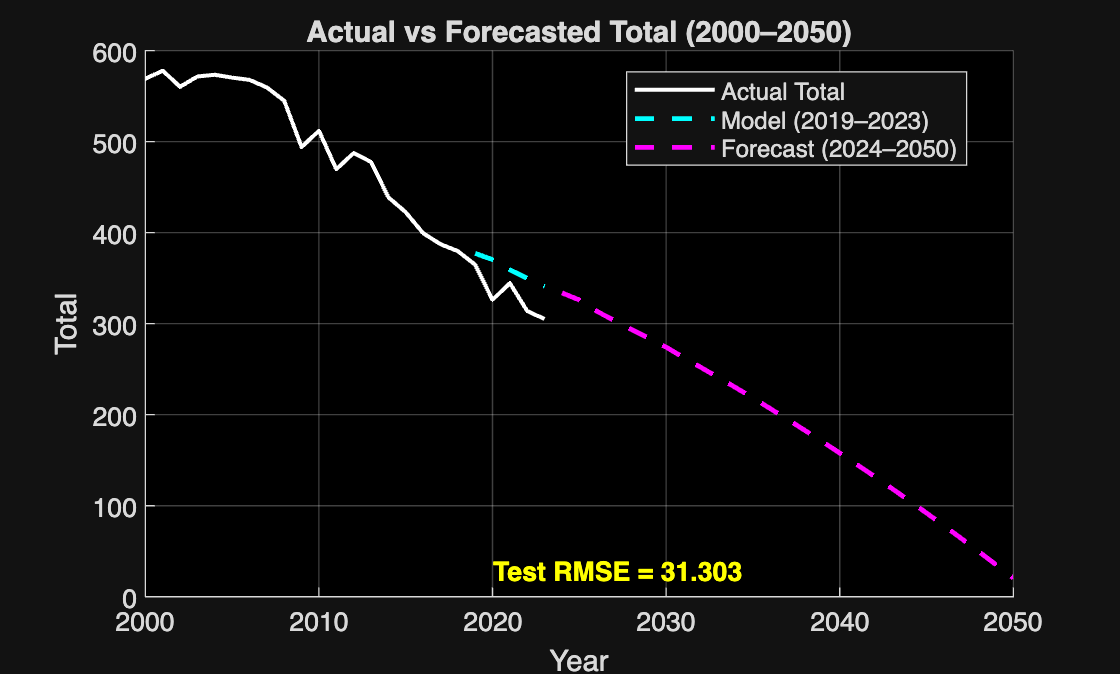

%% --- Plot 2000–2050 with test RMSE and forecast ---
figure;
hold on;

% Actual data (2000–2023)
plot(merged.Year, merged.Total, 'w', 'LineWidth', 1.5, 'DisplayName', 'Actual Total');

% Model predictions (2019–2023 test)
plot(test.Year, yPredTest_orig, 'c--', 'LineWidth', 1.8, 'DisplayName', 'Model (2019–2023)');

% Long-term forecast (2024–2050)
plot(futureYears, yPredFuture_orig, 'm--', 'LineWidth', 1.8, 'DisplayName', 'Forecast (2024–2050)');

% RMSE annotation
text(2020, min(merged.Total)*1.05, ...
    sprintf('Test RMSE = %.3f', testRMSE_orig), ...
    'Color', 'y', 'FontSize', 10, 'FontWeight', 'bold');

xlabel('Year');
ylabel('Total');
title('Actual vs Forecasted Total (2000–2050)');
xlim([2000 2050]);    % <-- limit visible years
legend('Location', 'best');
grid on;
set(gca, 'Color', 'k');
hold off;

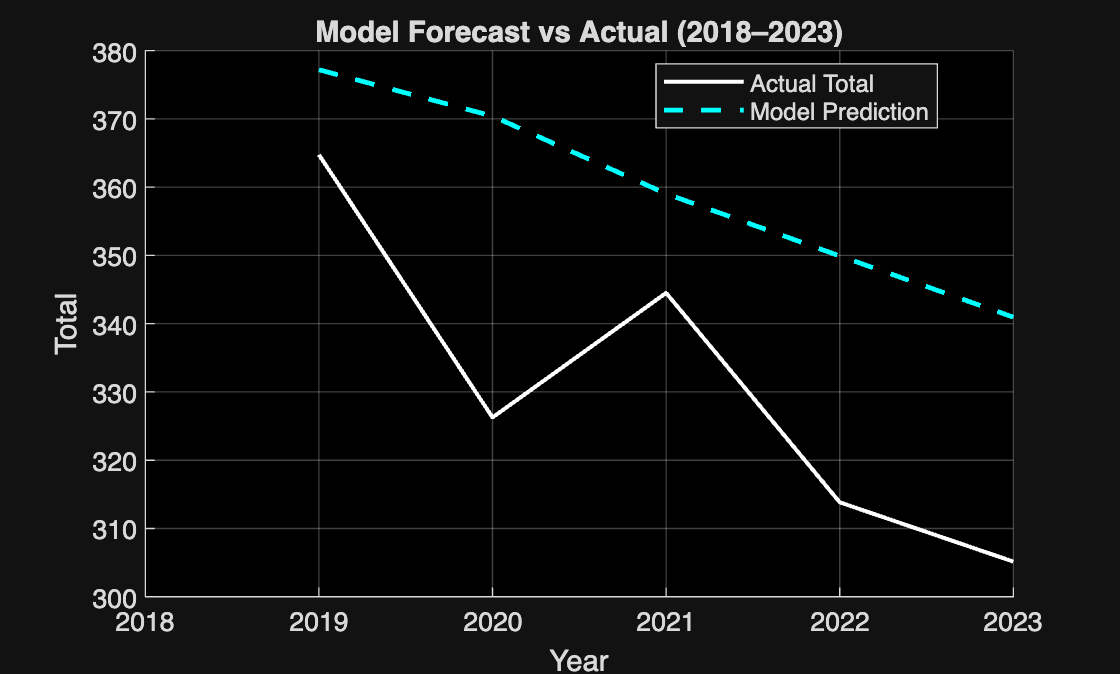

%% --- Plot Zoomed-In Test Period (2018–2023) ---
figure;
hold on;

% Actual Total for 2018–2023
plot(test.Year, test.Total, 'w', 'LineWidth', 1.5, 'DisplayName', 'Actual Total');

% Model Predictions for 2019–2023
plot(test.Year, yPredTest_orig, 'c--', 'LineWidth', 1.8, 'DisplayName', 'Model Prediction');

xlabel('Year');
ylabel('Total');
title('Model Forecast vs Actual (2018–2023)');
legend('Location', 'best');
xlim([2018 2023]);
grid on;
set(gca, 'Color', 'k');
hold off;

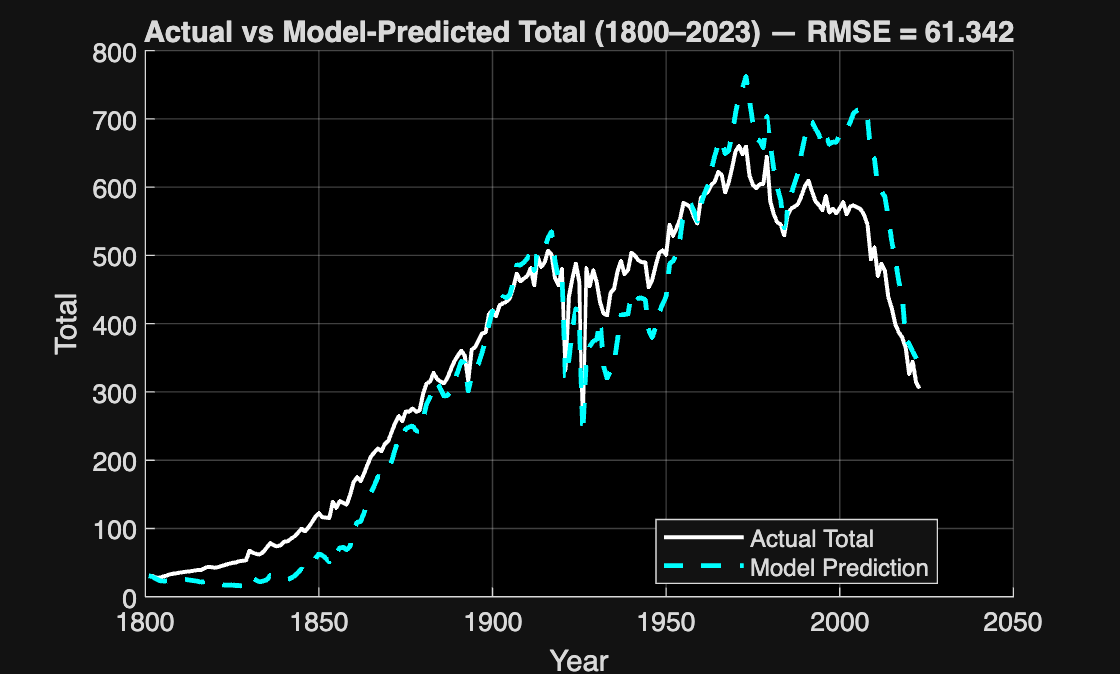

%% --- Actual vs Model-Predicted Total (1800–2023) with RMSE ---

% 1. Get in-sample fitted differenced values
yfitted = infer(finalFit, train_valid.Total_diff, 'X', train_valid.Population);

% 2. Reconstruct fitted (detrended) levels
base_detr = train_valid.Total_detrended(1);
yfit_detr = base_detr + cumsum(yfitted);

% 3. Add back trend to return to original scale
yrs_mean = mean(yrs);
trend_fit = polyval(p, train_valid.Year - yrs_mean);
yfit_orig = yfit_detr + trend_fit;

% 4. Compute RMSE across full 1800–2023 span (train + test)
trueAll = merged.Total(merged.Year <= 2023);
predAll = [yfit_orig; yPredTest_orig];
yearAll = [train_valid.Year; test.Year];
overallRMSE = sqrt(mean((trueAll - predAll).^2, 'omitnan'));

% 5. Plot actual vs model prediction
figure;
hold on;
plot(merged.Year, merged.Total, 'w', 'LineWidth', 1.5, 'DisplayName', 'Actual Total');
plot(yearAll, predAll, 'c--', 'LineWidth', 1.8, 'DisplayName', 'Model Prediction');
xlabel('Year');
ylabel('Total');
title(sprintf('Actual vs Model-Predicted Total (1800–2023) — RMSE = %.3f', overallRMSE));
legend('Location', 'best');
grid on;
set(gca, 'Color', 'k');
hold off;